# Problema 3

Tercer examen parcial.

h = 0.01;
m1 = 0.05; m2 = m1;
k1 = 0.01; k2 = k1; k3 = k2;
b = 0.0125;

xv0 = [0.025;-0.025; 0; 0]

xv0 =    0.025000000000000
  -0.025000000000000
                   0
                   0



M = [0, 0, 1, 0; 0, 0, 0, 1; -(k1+k2)/m1, k2/m1, -b/m1, 0; k2/m2, -(k2+k3)/m2, 0, -b/m2]

M =                    0                   0   1.000000000000000                   0
                   0                   0                   0   1.000000000000000
  -0.400000000000000   0.200000000000000  -0.250000000000000                   0
   0.200000000000000  -0.400000000000000                   0  -0.250000000000000


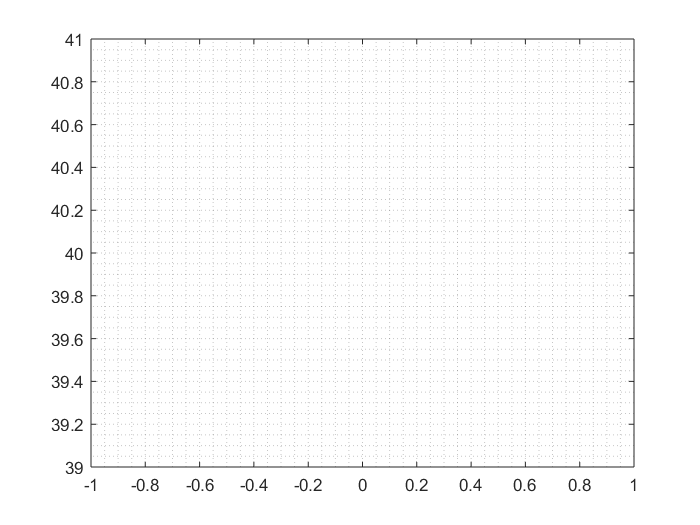


f = @(t, xv) M*xv;

[t,y] = ivps(f,0,40,xv0,h,'trapezoide');
plot(t,y(1,:));
grid minor

lambda = eig(M)

lambda =  -0.125000000000000 + 0.764444242571033i
 -0.125000000000000 - 0.764444242571033i
 -0.125000000000000 + 0.429389100932942i
 -0.125000000000000 - 0.429389100932942i


w = imag(lambda(:,1))

w =    0.764444242571033
  -0.764444242571033
   0.429389100932942
  -0.429389100932942


f = w/(2*pi)

f =    0.121665079923320
  -0.121665079923320
   0.068339397923262
  -0.068339397923262


T = 1./f

T =    8.219285275859407
  -8.219285275859407
  14.632847674819859
 -14.632847674819859
